# Diagnostics - USRP Attacking Subsystem

## Initialize the configuration to test against

clear;
clf;
simulator = Simulator_revB();
kristen_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
windows_file_path = "C:\Users\Operator\Documents\RadarSecurityResearch\MATLAB\Simulink Model\config_files\";
david_path = "/home/david/Documents/BlackBoxRadarAttacks/MATLAB/config_files/";
% file_path = "20MHz_USRP.json";
file_path = "20MHz_USRP_revA.json";
% file_path = "20MHz_USRP_revB.json";
% file_path = "20MHz.json";
% file_path = "100MHz.json";
% file_path = "100MHz_USRP.json";
% file_path = "1GHz.json";
% file_path = "4GHz.json";
simulator.load_params_from_JSON(david_path + file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_usrp_attacker_and_victim_position_and_velocity();

%print out key parameters

simulator.Victim.print_radar_parameters;

Chirp Parameters
	 Start Frequency: 		 1.50 GHz
	 Frequency Slope: 		 0.05 MHz/us
	 Idle Time: 			 1.92 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 7.68 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 0.52 MSps
	 Ramp End Time: 		 499.20 us
	 Chirp Tx Bandwidth: 		 25.00 MHz
	 Chirp Sampling Bandwidth: 	 24.62 MHz
	 ADC Sampling Period: 		 491.52 us
	 Chirp Cycle Time: 		 501.12 us
	 Chirp Wavelength: 		 199.86 mm
Frame Parameters
	 Number of Chirps 		 256
	 FramePeriodicity 		 400.40 ms
	 Active Frame Time 		 128.29 ms
Performance Specifications
	 Max Range 			 1558.92 m
	 Range Resolution 		 6.09 m
	 Max Velocity 			 99.71 m/s
	 Velocity Resolution 		 0.78 m/s
FMCW Specifications
	 FMCW sampling rate 		 25.00 MHz
	 Downsampling factor 		 48
	 Sweep time 			 499.20 us
	 Samples per chirp 		 12528.00 
CFAR Detection Region
	 Range Detection Region 		 24.358 m to 1528.476 m
	 Velocity Detection Region 		 -77.896 m/s to 78.675 m/s


### Precompute victim chirps

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

## Save the victim chirp to a file

%save the full chirp as a binary file
path = "/home/david/Documents/MATLAB_generated/MATLAB_full_chirps/MATLAB_chirp_full.bin";
simulator.save_to_file(simulator.Victim.chirp,path,'float32');

### Plot Tx Chirp to confirm correctness

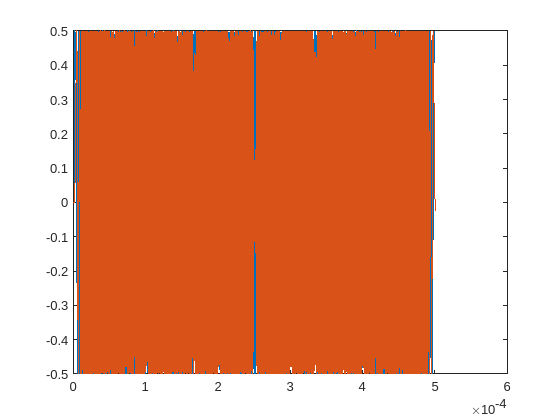

%plot the chirp signal
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
data = 0.5 * simulator.Victim.chirp;
plot(t,real(data),t,imag(data))

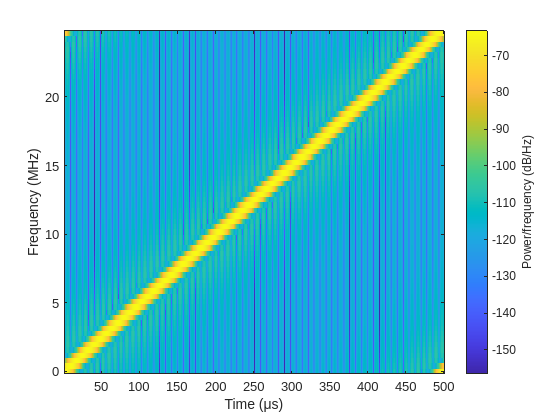

spectrogram(data,64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

## RUN ATTACK ON MATLAB

### Read Rx data from MATLAB

path = "/home/david/Documents/MATLAB_generated/cpp_rx_data_files/cpp_rx_data.bin";
read_data = simulator.read_from_file(path,true,"float");

num_chirps = simulator.Victim.NumChirps;
samples_per_chirp = simulator.Victim.ChirpCycleTime_us * 1e-6 * simulator.Victim.FMCW_sampling_rate_Hz;
read_data = reshape(read_data,int32(samples_per_chirp),num_chirps,[]);

%determine the number of frames recorded
% num_frames = size(read_data,3);
num_frames = 15;

### Configure the movie to focus in on specific arease of the range-doppler and CFAR plots

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
target_pos = 50;
target_vel = 10;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(num_frames, ...
    record_movie,target_pos,-1 * target_vel,30);

### Plot Rx Chirp to confirm correctness

Specify chirp:

chirp =46;

Specify frame:

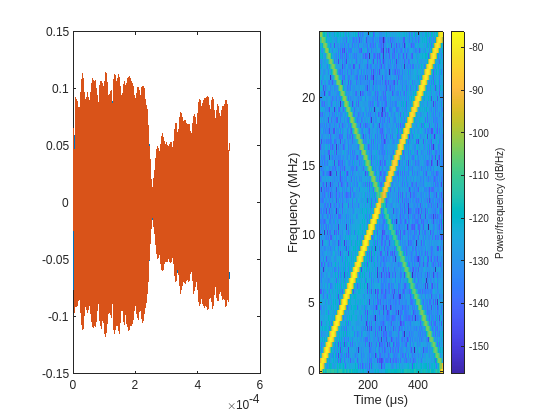

frame = 12;
first_frame = read_data(:,:,1);
t = 0:simulator.Victim.FMCW_sampling_period_s:...
    simulator.Victim.ChirpCycleTime_us * 1e-6 - ...
    simulator.Victim.FMCW_sampling_period_s;
clf;
subplot(1,2,1);
plot(t,real(read_data(:,chirp,frame)),t,imag(read_data(:,chirp,frame)))
subplot(1,2,2)
spectrogram(read_data(:,chirp,frame),64,48,64,simulator.Victim.FMCW_sampling_rate_Hz,'yaxis')

### Initialize the Victim and Simulation Parameters

%specify the number of frames and chirps to compute
clf;
% num_frames = size(read_data,3);
% num_chirps = simulator.Victim.NumChirps;
% num_frames = 30;

%reset the movie and range estimates
% simulator.Victim.Radar_Signal_Processor.F_rngdop = struct('cdata',[],'colormap',[]);
% simulator.Victim.Radar_Signal_Processor.F_clusters = struct('cdata',[],'colormap',[]);
% simulator.Victim.Radar_Signal_Processor.range_estimates = [];
% simulator.Victim.Radar_Signal_Processor.velocity_estimates = [];

%specify whether or not to record a move of the range-doppler plot
% record_movie = true;
% simulator.Victim.Radar_Signal_Processor.configure_movie_capture(num_frames, ...
%     record_movie,target_pos,-1 * target_vel,80);

%pre-compute the victim's chirps
% simulator.Victim.precompute_radar_chirps();

### Process Received Rx Signal

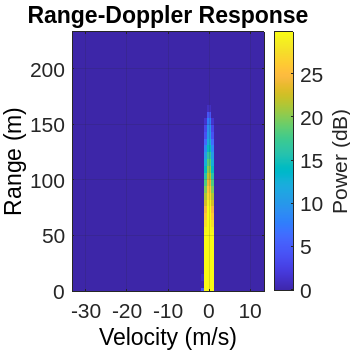

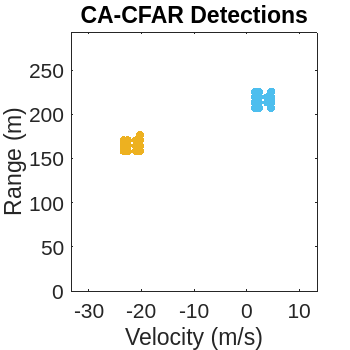

%get the radar chirp generator and the target emulator ready
clf;
simulator.Victim.precompute_radar_chirps();

for frame = int32(1:num_frames)
    
    %initialize a clean radar cube
    simulator.Victim.Radar_Signal_Processor.reset_radar_cube();
    simulator.Victim.current_frame = frame;
    
    for chirp = int32(1:num_chirps)
    
        %get the Tx chirp and the chirp received from the emulator
        Rx_sig = read_data(:,chirp,frame);
        Tx_sig = simulator.Victim.chirps(:,chirp);      
                
        %assemble the radar cube
        simulator.Victim.Radar_Signal_Processor.update_radar_cube(Tx_sig,Rx_sig,chirp);
    end

    simulator.Victim.Radar_Signal_Processor.process_radar_cube();
end

## Results

%get the estimated ranges and velocities
range_detections = simulator.Victim.Radar_Signal_Processor.range_estimates

range_detections = 1.0e+03 *

    1.1202    0.5593    0.0518    0.3818    0.4528
    1.1200    0.5593    0.0518    0.3821    0.4981
    1.2304    1.1203    0.5594    0.0518    0.4047
    1.1197    0.5594    0.0518    0.3818    0.4978
    1.2306    1.1198    0.5594    0.0518    0.3821
    1.2303    1.1198    0.5595    0.0518    0.3817
    1.1204    0.5594    0.0518    0.3816    0.4529
    1.1194    0.5593    0.0518    0.4041    0.4527
    1.1198    0.5592    0.0518    0.3818    0.4534
    1.1202    0.5592    0.0518    0.3821    0.4523


velocity_detections = simulator.Victim.Radar_Signal_Processor.velocity_estimates

velocity_detections =    44.1672   22.0073   -0.0008   -0.0126    0.0130
   44.1998   22.0004   -0.0019   -0.0155    0.0290
   -0.0155   44.1566   22.0239   -0.0034   -0.0029
   44.1696   22.0046   -0.0000    0.0082   -0.0337
   -0.0275   44.1689   22.0116    0.0000    0.0078
    0.0167   44.1575   22.0202    0.0021   -0.0122
   44.1524   22.0132    0.0026    0.0058   -0.0086
   44.0798   21.9863   -0.0006   -0.0096    0.0170
   44.1215   22.0117    0.0002   -0.0018   -0.0140
   44.1155   21.9903   -0.0001   -0.0100    0.0038


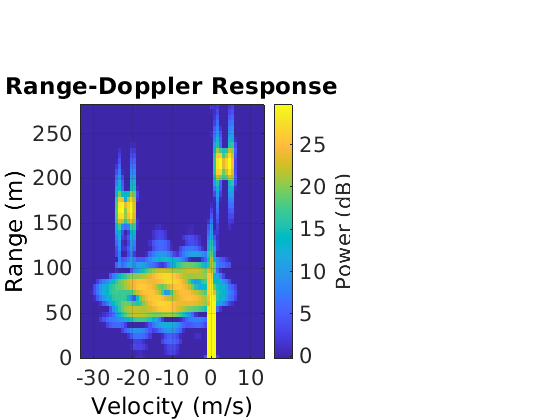

%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

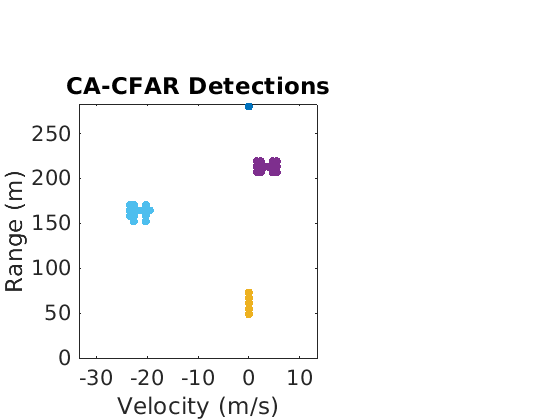

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end

#### Generating Clustering and Range-Doppler Response Figures

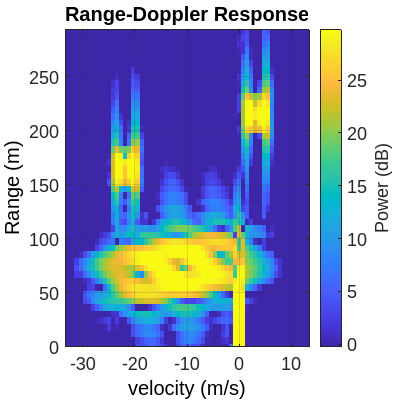

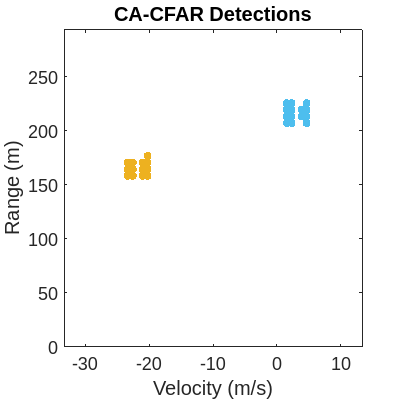

%range-doppler response
clf;
[resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(...
    simulator.Victim.Radar_Signal_Processor.radar_cube);
resp_max = 10*log10(abs(max(resp,[],"all")));

%CA CFAR 2-D
detections = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(...
    abs(resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);
detected_velocities = dopgrid(detections(2,:));
detected_ranges = rnggrid(detections(1,:));



%estimate the range and the velocities
if ~isempty(detections)

    %DBSCAN Clustering
    idx = dbscan(detections.',...
        simulator.Victim.Radar_Signal_Processor.Epsilon,...
        simulator.Victim.Radar_Signal_Processor.minpts);

    %plot the range-doppler and clustering responses
    
    %plot range doppler
    plotResponse( ...
        simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
        simulator.Victim.Radar_Signal_Processor.radar_cube);
    
    %zoom the range doppler plot
    tgt_velocity = simulator.Victim.Radar_Signal_Processor.tgt_velocity;
    tgt_range = simulator.Victim.Radar_Signal_Processor.tgt_range;
    num_bins_zoom = simulator.Victim.Radar_Signal_Processor.num_bins_zoom;

    clim([resp_max-30, resp_max]);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])
    
    font_size = 14;
    h = colorbar;
    h.FontSize = font_size;
    h.Label.String = "Power (dB)";
    h_label = h.Label;
    set(gcf,'Position',[100 100 400 400])
    title("Range-Doppler Response","FontSize",font_size)
    xlabel("velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/range_doppler",'-dsvg')
    print('-r300',"generated_plots/range_doppler",'-dpng')

    %plot the clusters
    gscatter(detected_velocities,detected_ranges,idx);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])

    font_size = 14;
%     colorbar(gca,"FontSize",font_size)
    legend('off')
    set(gcf,'Position',[100 100 400 400])
    title("CA-CFAR Detections","FontSize",font_size)
    xlabel("Velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/clustering",'-dsvg')
    print('-r300',"generated_plots/clustering",'-dpng')
else
    %plot range doppler
    plotResponse( ...
        simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse, ...
        simulator.Victim.Radar_Signal_Processor.radar_cube);
    
    %zoom the range doppler plot
    tgt_velocity = simulator.Victim.Radar_Signal_Processor.tgt_velocity;
    tgt_range = simulator.Victim.Radar_Signal_Processor.tgt_range;
    num_bins_zoom = simulator.Victim.Radar_Signal_Processor.num_bins_zoom;

    clim([resp_max-30, resp_max]);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])
    
    font_size = 14;
    h = colorbar;
    h.FontSize = font_size;
    h.Label.String = "Power (dB)";
    h_label = h.Label;
    set(gcf,'Position',[100 100 400 400])
    title("Range-Doppler Response","FontSize",font_size)
    xlabel("Velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/range_doppler",'-dsvg')
    print('-r300',"generated_plots/range_doppler",'-dpng')


    %plot the clusters
    clf;
    detected_velocities = [0];
    detected_ranges = [0];
    idx = [1];
    gscatter(detected_velocities,detected_ranges,idx);
    xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])
    ylim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
        - num_bins_zoom * simulator.Victim.Range_Res_m,...
        0), ...
        min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
        * tgt_velocity) ...
        + num_bins_zoom * simulator.Victim.Range_Res_m,...
        simulator.Victim.Range_Max_m)])
    cla;
    font_size = 14;
%     colorbar(gca,"FontSize",font_size)
    legend('off')
    set(gcf,'Position',[100 100 400 400])
    title("CA-CFAR Detections","FontSize",font_size)
    xlabel("Velocity (m/s)","FontSize",font_size)
    ylabel("Range (m)","FontSize",font_size)
    ax = gca;
    ax.FontSize = font_size;
    print('-r300',"generated_plots/clustering",'-dsvg')
    print('-r300',"generated_plots/clustering",'-dpng')
end

### Generate a subplot sampling of multiple frames for a preview of the movie

% clf;
% figure('Position',[1,1,900,800]);
% axis fill;
% num_frames = 30
% tiledlayout(2,2,TileSpacing="none",Padding="tight")
% 
%     %subplot of the Doppler in the left column
%     nexttile
%     [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(1)));
%     imshow(X,map)
%     nexttile
%     [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_rngdop(ceil(num_frames)));
%     imshow(X,map)
% 
%     %subplot of the clustering in the right column
%     nexttile
%     [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(1)));
%     imshow(X,map)
%     nexttile
%     [X,map] = frame2im(simulator.Victim.Radar_Signal_Processor.F_clusters(ceil(num_frames)));
%     imshow(X,map)
% 
% print('-r500',"generated_plots/attack_timeline",'-dsvg')
% print('-r500',"generated_plots/attack_timeline",'-dpng')

## Evaluating CFAR Performance with surf plots

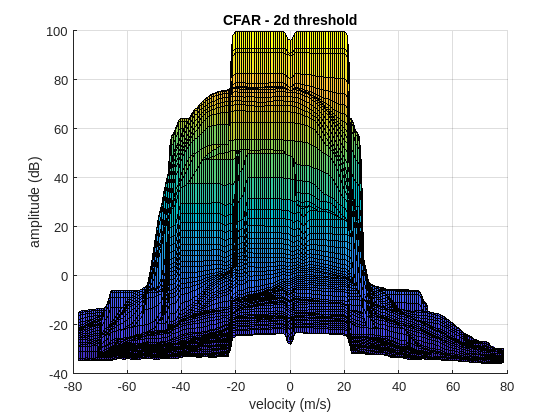

clf;
figure;

%evaluate the 2d CFAR detections for the desired frame
radar_cube = simulator.Victim.Radar_Signal_Processor.radar_cube;
[frame_resp, rnggrid,dopgrid] = simulator.Victim.Radar_Signal_Processor.RangeDopplerResponse(radar_cube);
CUT_indicies = simulator.Victim.Radar_Signal_Processor.CUT_indicies;

%configure the CFAR
release(simulator.Victim.Radar_Signal_Processor.CFARDetector2D);
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.ThresholdOutputPort = true;
simulator.Victim.Radar_Signal_Processor.CFARDetector2D.OutputFormat ="CUT result";


%compute the CFAR
[detections,th] = simulator.Victim.Radar_Signal_Processor.CFARDetector2D(abs(frame_resp).^2,simulator.Victim.Radar_Signal_Processor.CUT_indicies);

%determine range indicies in threshold detector
ranges = rnggrid(CUT_indicies(1,:)); %y
velocities = dopgrid(CUT_indicies(2,:)); %x


dopgrid_th = linspace(min(velocities), max(velocities),max(CUT_indicies(2,:)) - min(CUT_indicies(2,:) - 1));
rnggrid_th = linspace(min(ranges), max(ranges),max(CUT_indicies(1,:)) - min(CUT_indicies(1,:) - 1));
[X,Y] = meshgrid(dopgrid_th, rnggrid_th);

%convert the thresholds to db
th = 20 * log10(th);

th_surface = griddata(velocities,ranges,th,X,Y);
surf(X, Y, th_surface);
view(0,0);
title("CFAR - 2d threshold");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

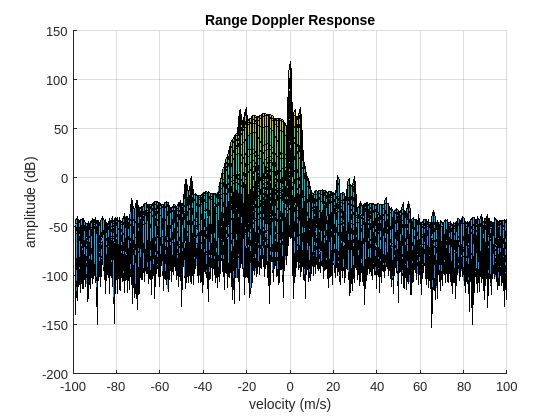


%convert the response to db
frame_resp = 20 * log10(abs(frame_resp).^2);
surf(dopgrid,rnggrid,frame_resp)
view(0,0);
title("Range Doppler Response");
xlabel("velocity (m/s)");
ylabel("range (m)");
zlabel("amplitude (dB)");

## Evaluating Range Performance

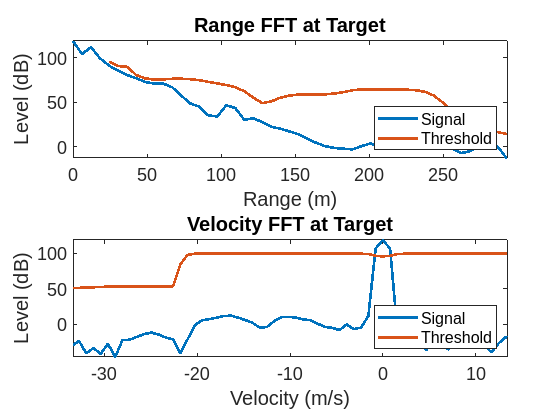

%find the maximum point
[M,I] = max(frame_resp,[],'all');
[rng_idx,vel_idx] = find(frame_resp == M);

%compute the indicies for the computed threshold
rng_idx_th = find(abs(rnggrid_th - rnggrid(rng_idx)) < 1e-4);
if isempty(rng_idx_th)
    rng_idx_th = 1;
end
vel_idx_th = find(abs(dopgrid_th - dopgrid(vel_idx)) < 1e-4);
if isempty(vel_idx_th)
    vel_idx_th = 1;
end

%plot range
rng_fft = frame_resp(:,vel_idx);
rng_th = th_surface(:,vel_idx_th);

subplot(2,1,1) 
plot(rnggrid,rng_fft,rnggrid_th,rng_th,"LineWidth",2.0)

xlim([max(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3)...
    - num_bins_zoom * simulator.Victim.Range_Res_m,...
    0), ...
    min(tgt_range - (simulator.Victim.current_frame * simulator.Victim.FramePeriodicity_ms * 1e-3 ...
    * tgt_velocity) ...
    + num_bins_zoom * simulator.Victim.Range_Res_m,...
    simulator.Victim.Range_Max_m)])

font_size = 14;
title("Range FFT at Target","FontSize",font_size)
xlabel("Range (m)","FontSize",font_size)
ylabel("Level (dB)","FontSize",font_size)
ax = gca;
ax.FontSize = font_size;
legend('Signal','Threshold','Location','Southeast')

%plot velocity
dop_fft = frame_resp(rng_idx,:);
dop_th = th_surface(rng_idx_th,:);

subplot(2,1,2) 
plot(dopgrid,dop_fft,dopgrid_th,dop_th, "lineWidth",2.0)
legend('Signal','Threshold','Location','Southeast')
xlabel('Velocity')
ylabel('Level')
title("Velocity FFT at target")

xlim([max(tgt_velocity - num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        -1 * simulator.Victim.V_Max_m_per_s), ...
        min(tgt_velocity + num_bins_zoom * simulator.Victim.V_Res_m_per_s, ...
        simulator.Victim.V_Max_m_per_s)])

font_size = 14;
title("Velocity FFT at Target","FontSize",font_size)
xlabel("Velocity (m/s)","FontSize",font_size)
ylabel("Level (dB)","FontSize",font_size)
ax = gca;
ax.FontSize = font_size;

%save the plots
% print('-r300',"generated_plots/CFAR_output",'-dsvg')
print('-r300',"generated_plots/CFAR_output",'-dpng')

Generate plot of IF signals

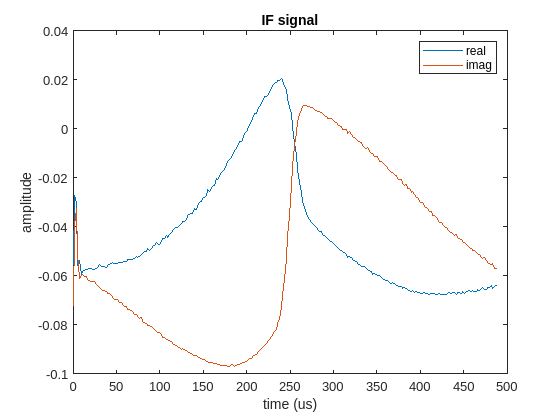

sampled_IF_sig = simulator.Victim.Radar_Signal_Processor.radar_cube(:,1);
inter_sample_period = 1/simulator.Victim.ADC_SampleRate_MSps;
times = 0:inter_sample_period:(simulator.Victim.ADC_Samples - 1) * inter_sample_period;
clf;
plot(times,real(sampled_IF_sig),times, imag(sampled_IF_sig));
legend("real","imag")
xlabel("time (us)")
ylabel("amplitude")
title("IF signal")
print('-r300',"generated_plots/if_signal",'-dsvg')
print('-r300',"generated_plots/if_signal",'-dpng')

#### Plot Range FFT

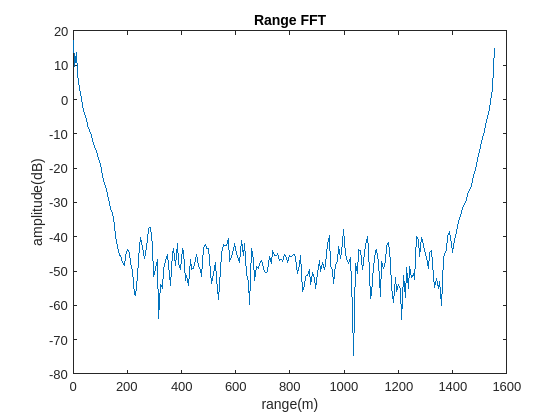

window = hann(simulator.Victim.ADC_Samples);
windowed_sig = window .* radar_cube(:,1);
range_fft = 20 * log10(abs(fft(windowed_sig)));
clf;
plot(simulator.Victim.Ranges,range_fft)
title("range FFT at target")
xlabel("range(m)")
ylabel("amplitude(dB)")
title("Range FFT")
print('-r300',"generated_plots/Range_fft",'-dsvg')
print('-r300',"generated_plots/Range_fft",'-dpng')

## Code to align the rx and the tx signal using cross correlation

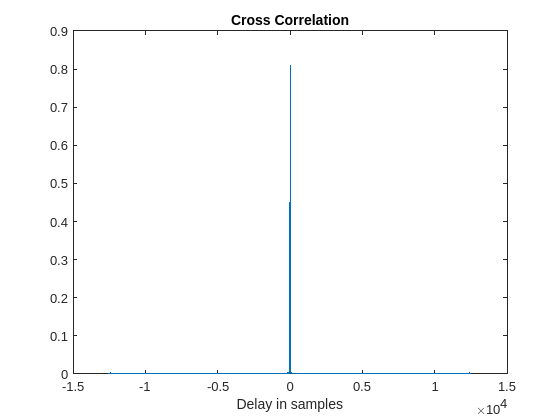

[C,lag] = xcorr(Rx_sig,Tx_sig,"normalized");
clf;
plot(lag,abs(C));
xlabel("Delay in samples")
title("Cross Correlation")

[M,I] = max(abs(C));
delay_samps = lag(I)

delay_samps = 0

delay_us = delay_samps * simulator.Victim.FMCW_sampling_period_s * 1e6

delay_us = 0

%positive lag is ahead of time (decrease the offset_us term)